clearvars; close all; clc;

% Load file information
folder_path = 'D:\Dropbox\Data\8-19-20 beas tubulin\';
cd(folder_path);
data_path = 'D:\Dropbox\Data\8-19-20 beas tubulin\Analysis\toleranced\';
step_size = 0.02;
frame_exposure = 0.04;
ruler_name = 'cell_6_dz_20_scan.tif';
image_name ='cell_6_dz_20_0.tif';
data_name = [image_name(1:end-4),'_dast_tol.mat'];
ruler_image = readtiff(ruler_name);
image = readtiff(image_name);

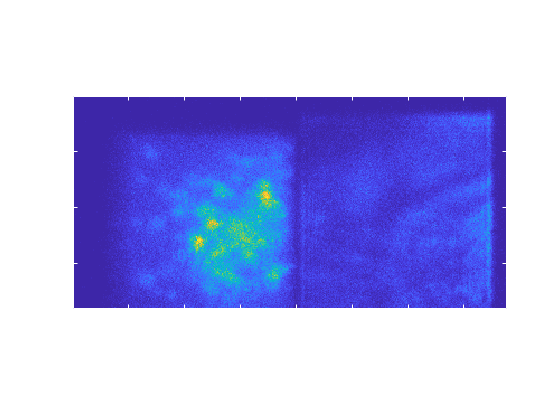

%Visualize Information
imagesc(ruler_image(:,:,1))
axis image

h = imagesc(ruler_image(:,:,1),[3 200])

h =   Image with properties:

           CData: [190×388 double]
    CDataMapping: 'scaled'

  Show all properties


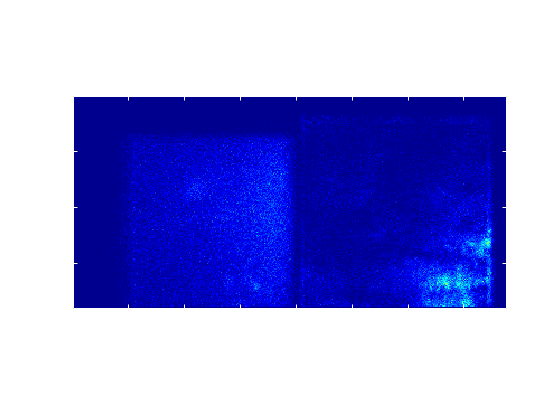

xlabel("Pixel")
ylabel("Pixel")
colormap('jet')
title("Example PAJF646 Frame with 637 nm Laser")
axis image
gif('Example of a ruler.gif','DelayTime',0.04)
for i = 2:numel(ruler_image(1,1,:))
    set(h,"CData",ruler_image(:,:,i))
    gif()
end

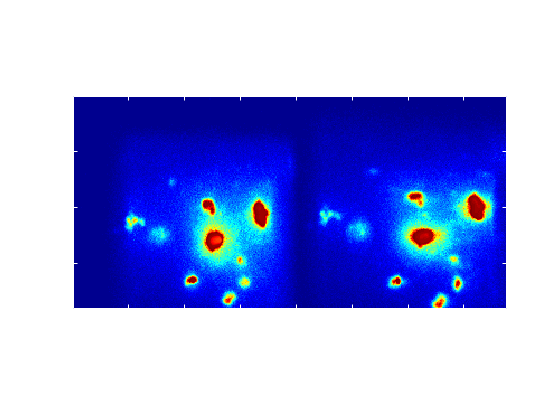





imagesc(image(:,:,1))
axis image
title('561 nm laser on')

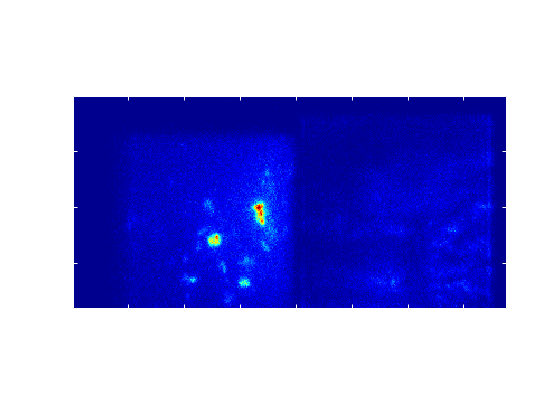

imagesc(image(:,:,2))
title('646 nm laser on')
axis image


channel_split = 200; % X position split in pixels
channel_split_end = 375; % end of channel cropping
channel_vertical_crop_start = 15;
[m,n,o] = size(ruler_image)

m = 190

n = 388

o = 200

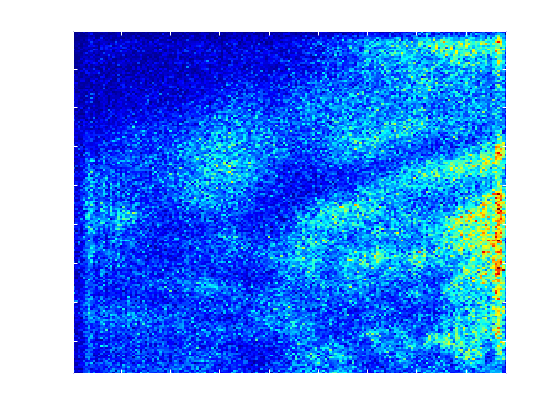

channel_vertical_crop_stop = m;
imagesc(ruler_image(channel_vertical_crop_start:channel_vertical_crop_stop,channel_split:channel_split_end,1))

sub_ruler_image = ruler_image(channel_vertical_crop_start:channel_vertical_crop_stop,channel_split:channel_split_end,:);

laser_images = image(channel_vertical_crop_start:channel_vertical_crop_stop,channel_split:channel_split_end,2:2:end);
h=imagesc(sub_ruler_image(:,:,1))

h =   Image with properties:

           CData: [176×176 double]
    CDataMapping: 'scaled'

  Show all properties


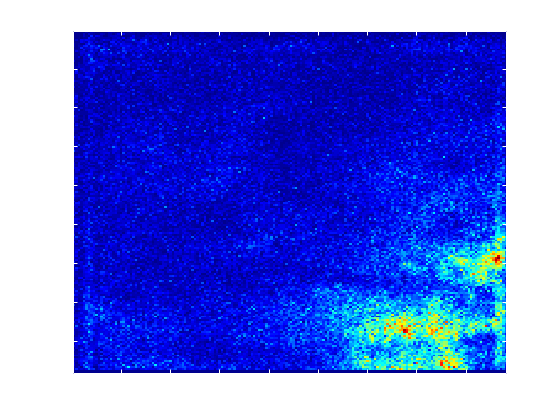

gif('Example of a cropped ruler.gif','DelayTime',0.04)
for i = 2:numel(sub_ruler_image(1,1,:))
    set(h,"CData",sub_ruler_image(:,:,i))
    gif()
end

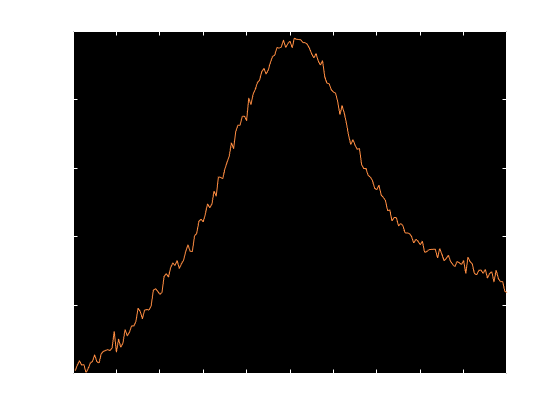

% Build ruler for subsequent measurment
[m,n,o] = size(sub_ruler_image);

C = zeros(o,1);
for i = 1:o
    C(i) = corr2(sub_ruler_image(:,:,i),laser_images(:,:,40));
end
plot(C)
xlabel('Sorted bleedthrough image index')
ylabel('2D X-Correlation')
title("Correlation values")


sub_C  = C(20:120);
max_corr = find(sub_C == max(sub_C));
min_corr = find(sub_C == min(sub_C));
plot(C(19+max_corr:19+min_corr));
title('Subset of Correlation values to ensure 1 slope')

ruler = sub_ruler_image(:,:,19+max_corr:19+min_corr);

% Parse image data to grab laser_sections
% Remember red channel is the even frames
laser_images = image(channel_vertical_crop_start:channel_vertical_crop_stop,channel_split:channel_split_end,2:2:end);

indexes = get_index_from_ruler(ruler,laser_images);

Array indices must be positive integers or logical values.

Error in two_channel_drift_with_ruler>get_index_from_ruler (line 133)
            indexes(i) = indexes(i-1);

indexes_raw = indexes;

% indexes_quartile_average = get_index_from_quartile_average(ruler,laser_images);

% Visualize the result
plot((1:numel(indexes))*2*frame_exposure,indexes_raw*step_size)
hold on
% plot([5250 5600, 5600, 5250, 5250], [0.08,0.08, 0.21,0.21,0.08] ,'r')
hold off
title("resulting 'whole image correlation' drift measurment")
xlabel('Time in Seconds')
ylabel('Relative drift in microns')

% Visualize the result
plot((1:numel(indexes))*2*frame_exposure,indexes_raw*step_size)

hold on
plot((1:numel(indexes))*2*frame_exposure,gausssmooth(indexes_raw, 5,10)*step_size)
% plot([5250 5600, 5600, 5250, 5250], [0.08,0.08, 0.21,0.21,0.08] ,'r')
plot([223.7 254.3, 254.3, 223.7, 223.7], [1.0774,1.0774, 1.1835,1.1835,1.0774] ,'k','LineWidth',2)
hold off
title("resulting whole image correlation drift measurment")
xlabel('Time in Seconds')
ylabel('Relative drift in microns')
legend('Raw measurement',['Gaussian average sigma = ',num2str(5*frame_exposure),'s'])% Visualize the result


%Load localization data and start correcting
load([data_path,data_name]);
z_correction = spline((2:2:2*numel(indexes_raw)), gausssmooth(indexes_raw, 5,10),cdata.red.framenumber)*step_size;
plot(cdata.red.framenumber,z_correction,'.')
title('Resulting z correction')

ind = cdata.red.zf < 0.5;
s = scatter3(cdata.red.xf(ind),cdata.red.yf(ind),-(cdata.red.zf(ind)-z_correction(ind)),3,cdata.red.framenumber(ind));
s.MarkerFaceColor = s.MarkerEdgeColor;
title('Scatter Plot of corrected localization')
colormap('jet')
axis equal
whitebg([0 0 0])



s = scatter3(cdata.red.xf(ind),cdata.red.yf(ind),cdata.red.zf(ind),3,cdata.red.framenumber(ind))

s.MarkerFaceColor = s.MarkerEdgeColor;
title('Scatter Plot of corrected localization')
colormap('jet')
axis equal
whitebg([0 0 0])


function indexes = get_index_from_ruler(ruler, image_stack)
    [m,n,o] = size(image_stack);
    [m,n,r] = size(ruler);
    indexes = zeros(o,1);
    for i = 1:o % loop over images
        C = [];
        for j = 1:r
           C(j) = corr2(ruler(:,:,j), image_stack(:,:,i));  
        end
        try
        indexes(i) = find(C == max(C));
        catch
            indexes(i) = indexes(i-1);
        end
    end
end

function indexes = get_index_from_quartile_average(ruler, image_stack)
    [m,n,o] = size(image_stack);
    [m,n,r] = size(ruler);
    indexes = zeros(o,1);
    for i = 1:o % loop over images
        C1 = zeros(r,1);
        C2 = zeros(r,1);
        C3 = zeros(r,1);
        C4 = zeros(r,1);
        % Quartile the image
        image_quarter_1 = image_stack(1:round(m/2),1:round(n/2),i);
        image_quarter_2 = image_stack(round(m/2):m,1:round(n/2),i);
        image_quarter_3 = image_stack(round(m/2):m,round(n/2):n,i);
        image_quarter_4 = image_stack(1:round(m/2),round(n/2):n,i);
        
        for j = 1:r
            % Quartile ruler
            ruler1 = ruler(1:round(m/2),1:round(n/2),j);
            ruler2 = ruler(round(m/2):m,1:round(n/2),j);
            ruler3 = ruler(round(m/2):m,round(n/2):n,j);
            ruler4 = ruler(1:round(m/2),round(n/2):n,j);
            
            C1(j) = corr2(ruler1, image_quarter_1);  
            C2(j) = corr2(ruler2, image_quarter_2);
            C3(j) = corr2(ruler3, image_quarter_3);
            C4(j) = corr2(ruler4, image_quarter_4);
            
        end
        ind(1) = find(C1 == max(C1));
        ind(2) = find(C2 == max(C2));
        ind(3) = find(C3 == max(C3));
        ind(4) = find(C4 == max(C4));
        indexes(i) = mean(ind);
    end
end